## Step 0: Initialization

clear;

rate = 48000; % sampling rate

% A chirp signal of 1 second 
% with a freq range of [1, 18]kHz 
x = audioread('chirp.wav');

groundTruth = 25; % cm

% Load data received by two different devices
y = struct();
y(1).raw = audioread(...
    ['devA_', num2str(groundTruth), 'cm.wav']);

y(2).raw = audioread(...
    ['devB_', num2str(groundTruth), 'cm.wav']);

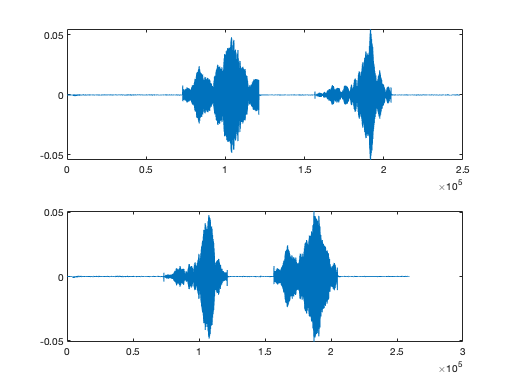

figure
subplot 211
plot(y(1).raw)

subplot 212
plot(y(2).raw)


size(x)

ans =        48000           1


## Step 1-1: Transfer function h(f) extraction (xcorr)

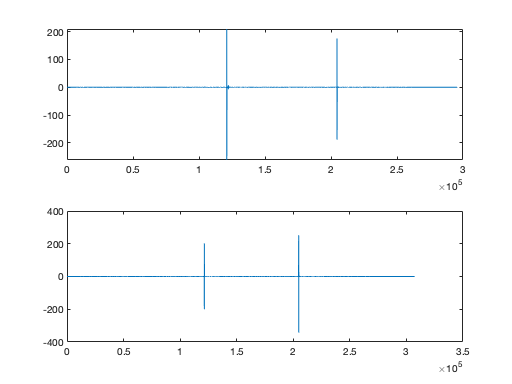

figure
for i = 1:2
    y(i).xcorr = conv(flipud(x), y(i).raw);
    
    subplot(2, 1, i)
    plot(y(i).xcorr)
end

## Step 1-2: EToA estimation (findpeaks)

for i = 1:2
    [vals, locs] = findpeaks(abs(y(i).xcorr), ...
        'MinPeakDistance', length(x));
    [~, idx] = sort(vals, 'descend');
    
    y(i).etoa = locs(idx(1:2)) ./ rate;
    y(i).etoa = sort(y(i).etoa);
    
    disp(y(i).etoa)
end

    2.5221
    4.2617

    2.5286
    4.2668




y(2).etoa = y(2).etoa + 10;
    disp(y(2).etoa)

   12.5286
   14.2668



## Step 2: Distance calculation

c = 34000; % cm/s
dAA = 3.5; % Spk-to-mic distance in devA
dBB = 3.5; % Spk-to-mic distance in devB

% c * (tB1 - tA1) + c * (tA3 - tB3) + (dAA + dBB)
distance = c * (y(2).etoa(1) - y(1).etoa(1)) ...
    + c * (y(1).etoa(2) - y(2).etoa(2)) ...
    + (dAA + dBB);

distance = distance / 2;

disp(['Ground truth: ', num2str(groundTruth)]);

Ground truth: 25


disp(['Estimated: ', num2str(distance)]);

Estimated: 27.2292
